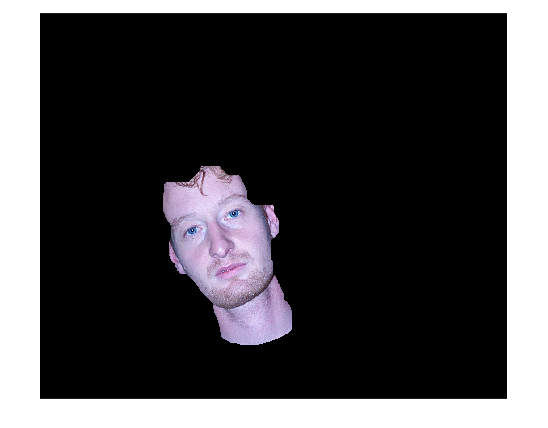

% Denna fil är för tnm034.m, bör användas av den
% tnm034 tar in en im, skickar ut ID av identifierad person.
% funkar när facemask appliceras korrekt, den gör ej på 5, 6, 11?
% senase versionen funkar alla
clear
im = imread("images/DB2/cl_10.jpg");
im = im2double(im); % konvertera till double pga faceMask funktionen kräver det

% vitbalans, endast för bilder med tonförändring
im = AWB_max(im);

% applicera facemask
facemask = skinDetection(im);
im = im.*facemask;
imshow(im);

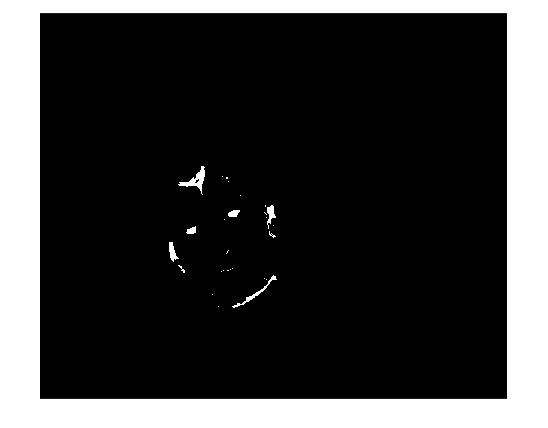


% munposition, om mouth_pos (0,0) hittades den inte
mouth_pos = mouthDetection(im);

% konvertera bilden till NTSC format för att enklare hitta eye dot genom chromasitet 
% använd endast luminocity kanalen
YIQim = rgb2ntsc(im);
imChrom = YIQim(:,:,1);

% bilddimensioner, används för att normalisera distanser för bilderna
im_height = length(imChrom(:,1)); im_width = length(imChrom(1,:));
im_area = im_height*im_width;
im_dist = round(sqrt(im_area));

% morfologi, dilation följt av erosion med 9x9 element och tar differensen
se1 = strel('disk', 9);
imOp = imopen(imChrom,se1);
imCl = imclose(imChrom,se1);
imDiff = imCl - imOp;

% Adaptiv tröskla genom bilden tills 6 blobbar med min area eller 2 med max area
thresh = 0.8; step = 0.05;
blob_minarea = round(im_area/10000); blobs_maxarea = round(im_area/1000);
counter_minarea = 0; counter_maxarea = 0;
imThresh = imDiff(:,:) > thresh;

while counter_minarea < 7 && counter_maxarea < 2 && thresh > 0.35
    counter_minarea = 0; counter_maxarea = 0;
    imThresh = imDiff(:,:) > thresh;
    blobs = regionprops(imThresh);
    blobs_amount = length(blobs(:));
    for i = 1:1:blobs_amount
        if blobs(i).Area > blob_minarea
            counter_minarea = counter_minarea + 1;
            if blobs(i).Area > blobs_maxarea
                counter_maxarea = counter_maxarea + 1;
            end
        end
    end
        thresh = thresh - step;
end
imshow(imThresh);

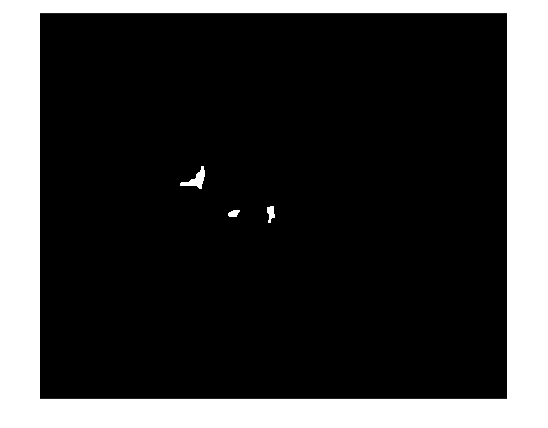


% Gör ögon tydligare, ta bort noise genom morfologisk stängning
se2 = strel('disk',3);
imThresh = imopen(imThresh,se2);
imThresh = imclose(imThresh,se2);

% ta bort blobbar från kanten som är under munnen samt är för långa
% Omringar området som tas bort med en låda vilket kan överlappa ögats blob
maxLength = im_dist/6;
h_remove = round(im_height/4);
blobs = regionprops(imThresh);
blobs_amount = length(blobs(:));
bottom =  mouth_pos(2) - (im_height/10);
if mouth_pos(1) == 0 && mouth_pos(2) == 0
    bottom = h_remove;
end
if blobs_amount > 2
    for i = 1:1:blobs_amount
        box = blobs(i).BoundingBox;
        if blobs(i).Centroid(2) > bottom || box(3) > maxLength || box(4) > maxLength
            imThresh(round(box(2)):round(box(4) + box(2)-1), round(box(1)):round(box(3) + box(1)-1)) = 0;
        end
    end
end
imshow(imThresh);

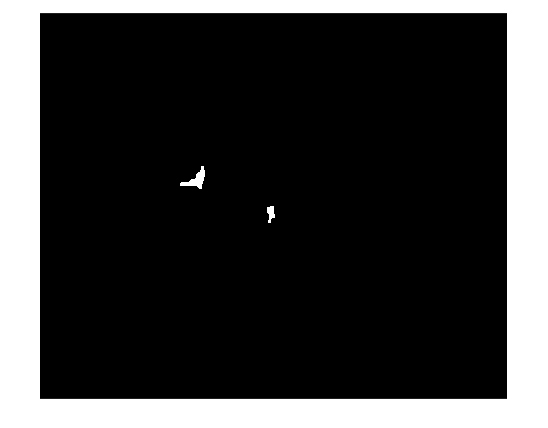


% ta ögon enligt munnens position (kollar vinkel)
if mouth_pos(1) > 0 && mouth_pos(2) > 0
    blobs = regionprops(imThresh);
    blobs_amount = length(blobs(:));
    angle_upper = 1.396263; % 80 grader
    angle_lower = 0.7853982; % 45 grader
    for blob_current = 1:1:(blobs_amount)
        hypotenuse = sqrt((blobs(blob_current).Centroid(1) - mouth_pos(1))^2 + (blobs(blob_current).Centroid(2) - mouth_pos(2))^2);
        perpendicular = abs(blobs(blob_current).Centroid(2) - mouth_pos(2));
        angle = asin(perpendicular/hypotenuse);
        if  angle > angle_upper || angle < angle_lower
            box = blobs(blob_current).BoundingBox;
            imThresh(round(box(2)):round(box(4) + box(2)-1), round(box(1)):round(box(3) + box(1)-1)) = 0;
        end
    end
end
imshow(imThresh);

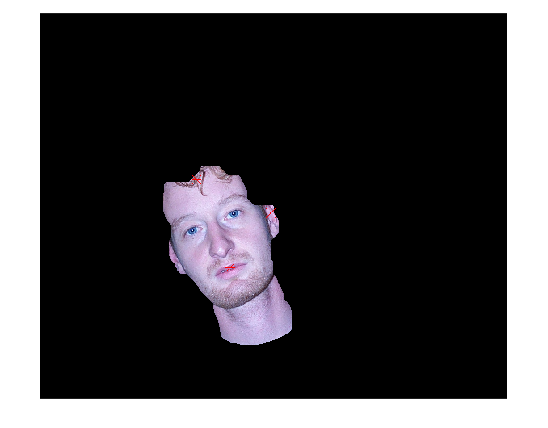

% Ifall det finns mer än 2 kvar ta endast dem 2 närmst till mun
blobs = regionprops(imThresh);
blobs_amount = length(blobs(:));
smallest1 = realmax('double'); smallest2 = realmax('double');
if blobs_amount > 2
    for blob_current = 1:1:blobs_amount
        hypotenuse = sqrt((blobs(blob_current).Centroid(1) - mouth_pos(1))^2 + (blobs(blob_current).Centroid(2) - mouth_pos(2))^2);
        if hypotenuse < smallest1
            smallest2 = smallest1;
            smallest1 = hypotenuse;
        elseif hypotenuse < smallest2
            smallest2 = hypotenuse;
        end
    end
    for blob_current = 1:1:blobs_amount
        hypotenuse = sqrt((blobs(blob_current).Centroid(1) - mouth_pos(1))^2 + (blobs(blob_current).Centroid(2) - mouth_pos(2))^2);
        if hypotenuse > smallest2
            box = blobs(blob_current).BoundingBox;
            imThresh(round(box(2)):round(box(4) + box(2)-1), round(box(1)):round(box(3) + box(1)-1)) = 0;
        end
    end
end

% DEBUG: Se resultat av algoritmen. Det borde endast finnas 2 vita blobbar som är ögonen 

% Få ögats position med regionprops, returnera värden
eyeStruct = regionprops(imThresh);
eyes_amount = length(eyeStruct(:));
if eyes_amount == 2
    eye1 = eyeStruct(1).Centroid;
    eye2 = eyeStruct(2).Centroid;
else
    eye1 = zeros(1,2);
    eye2 = zeros(1,2);
    % disp("ERROR: Could not find the eyes");
end
pos = [eye1; eye2; mouth_pos];
im = insertMarker(im, pos, 'star','color','red','size',10);
imshow(im);